## Lorenz Attractor

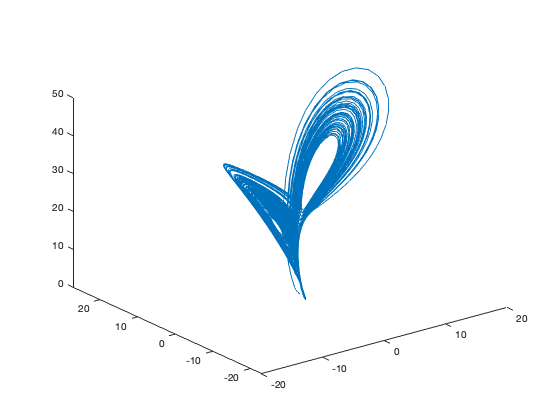

sigma = 10;
beta = 8/3;
rho = 28;
f = @(t,a) [-sigma*a(1) + sigma*a(2); rho*a(1) - a(2) - a(1)*a(3); -beta*a(3) + a(1)*a(2)];
[t,a] = ode45(f,[0 100],[1 1 1]);
plot3(a(:,1),a(:,2),a(:,3))